I1 = imread('Images/cat.jpg');
I2 = imread('Images/parrot.jpg');
I3 = imread('cameraman.tif');

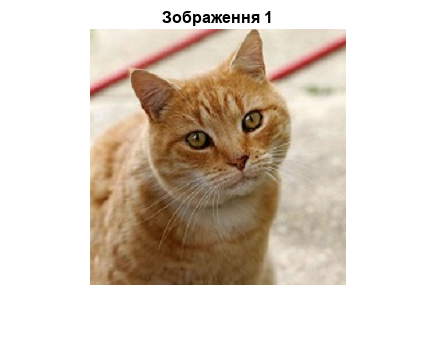

imshow(I1);  
title('Зображення 1');

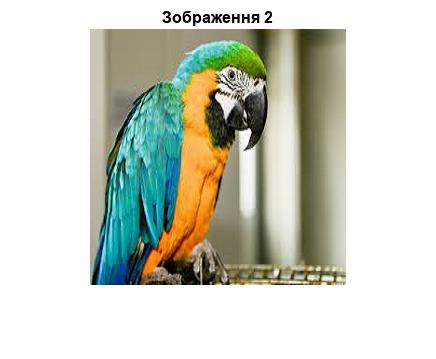

imshow(I2); 
title('Зображення 2');

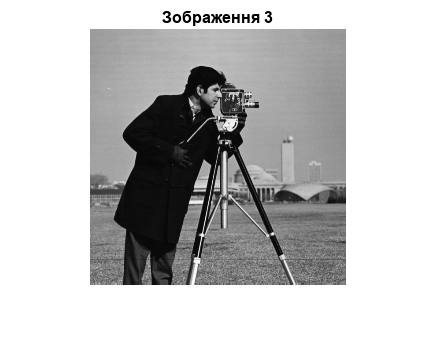

imshow(I3); 
title('Зображення 3');

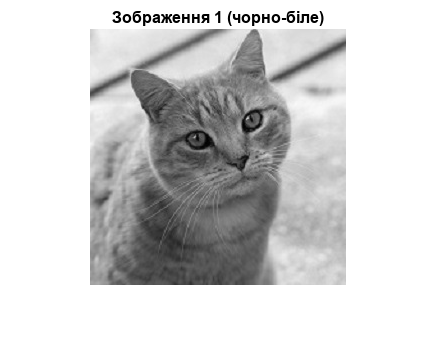

I1_gray = rgb2gray(I1);
imshow(I1_gray); 
title('Зображення 1 (чорно-біле)');

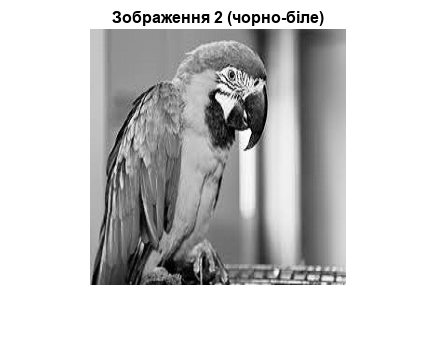

I2_gray = rgb2gray(I2);
imshow(I2_gray); 
title('Зображення 2 (чорно-біле)');

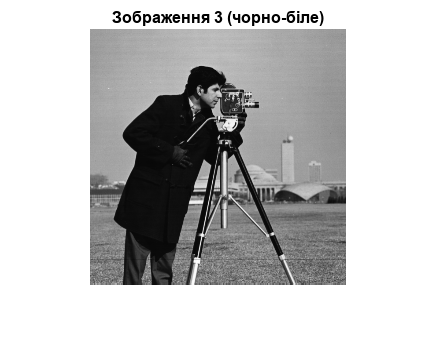

I3_gray = I3;
imshow(I3_gray); 
title('Зображення 3 (чорно-біле)');

I1_gray = im2double(I1_gray);
I2_gray = im2double(I2_gray);
I3_gray = im2double(I3_gray);

% задаємо розмір блока і створюємо матрицю
blockSize = 8;
T = dctmtx(blockSize);

dct_fun = @(block_struct) T * block_struct.data * T';

% поблочне ДКП для кожного зображення
DCT1 = blockproc(I1_gray, [blockSize blockSize], dct_fun);
DCT2 = blockproc(I2_gray, [blockSize blockSize], dct_fun);
DCT3 = blockproc(I3_gray, [blockSize blockSize], dct_fun);

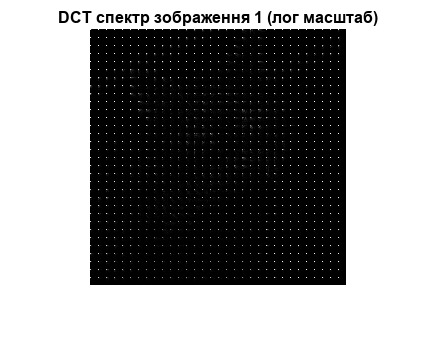

imshow(log(abs(DCT1) + 1), []); 
title('DCT спектр зображення 1 (лог масштаб)');

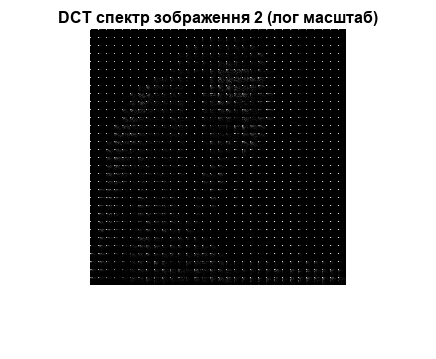



imshow(log(abs(DCT2) + 1), []); 
title('DCT спектр зображення 2 (лог масштаб)');

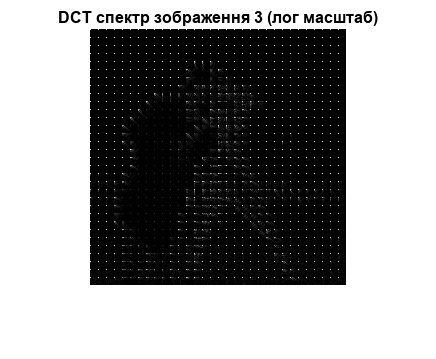


imshow(log(abs(DCT3) + 1), []); 
title('DCT спектр зображення 3 (лог масштаб)');

invdct = @(block_struct) T' * block_struct.data * T;

I1_restored = blockproc(DCT1, [blockSize blockSize], invdct);
I2_restored = blockproc(DCT2, [blockSize blockSize], invdct);
I3_restored = blockproc(DCT3, [blockSize blockSize], invdct);

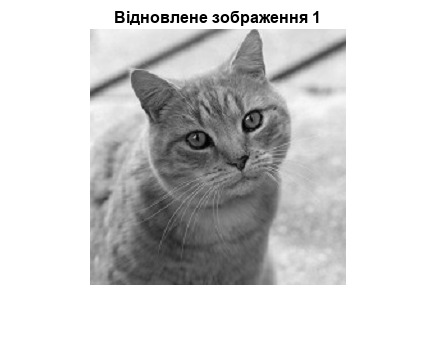

imshow(I1_restored); title('Відновлене зображення 1');

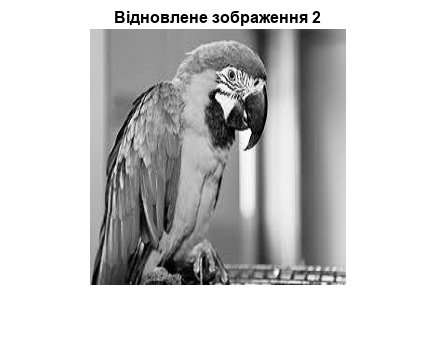

imshow(I2_restored); title('Відновлене зображення 2');

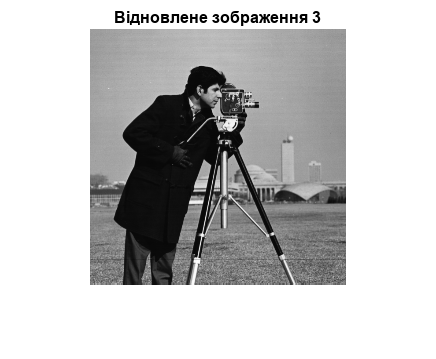

imshow(I3_restored); title('Відновлене зображення 3');

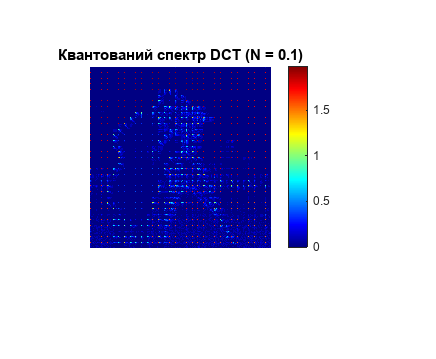

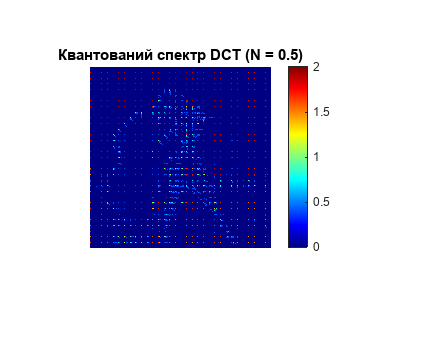

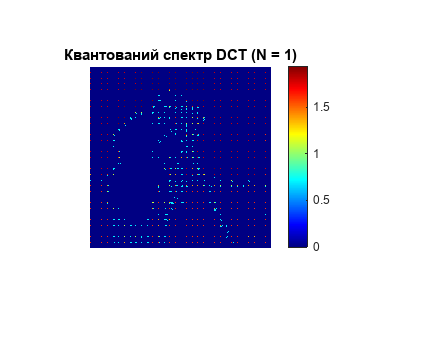

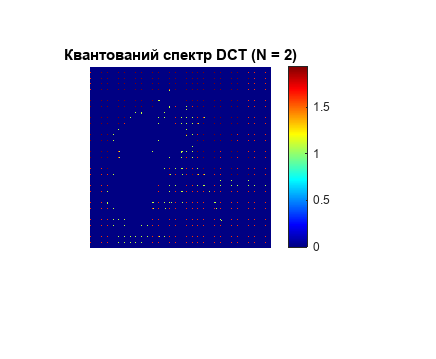

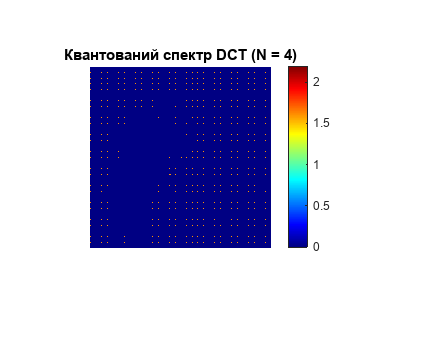

N_values = [0.1, 0.5, 1, 2, 4];

for i = 1:length(N_values)
    N = N_values(i);
    DCT1_q = N * round(DCT3 / N);
    
    figure;
    imshow(log(abs(DCT1_q) + 1), []); colormap(jet); colorbar;
    title(['Квантований спектр DCT (N = ', num2str(N), ')']);
end

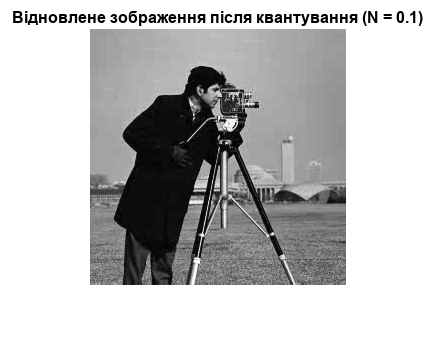

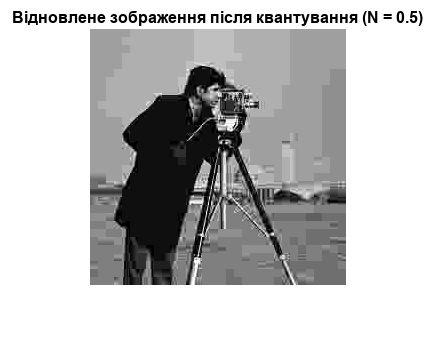

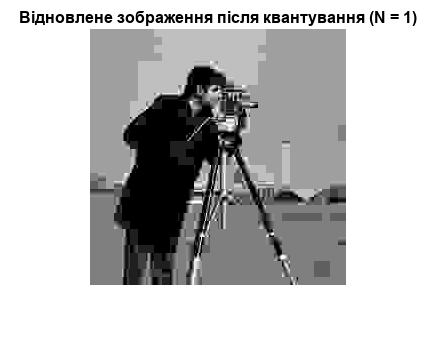

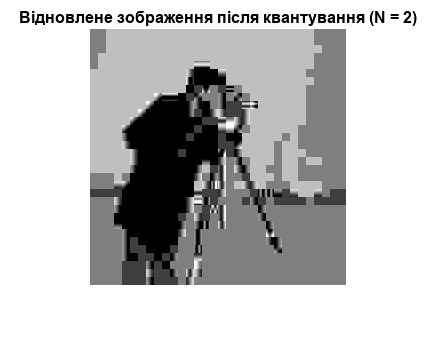

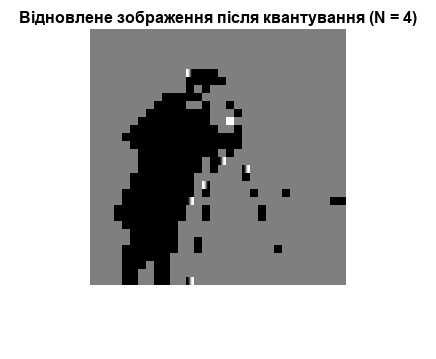

for i = 1:length(N_values)
    N = N_values(i);
    DCT1_q = N * round(DCT3 / N);
    I1_q_restored = blockproc(DCT1_q, [blockSize blockSize], invdct);
    
    figure;
    imshow(I1_q_restored);
    title(['Відновлене зображення після квантування (N = ', num2str(N), ')']);
end

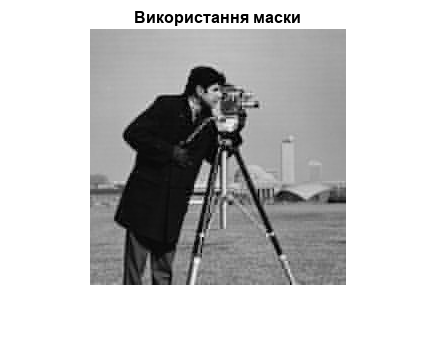

mask = [
    1 1 1 1 0 0 0 0;
    1 1 1 0 0 0 0 0;
    1 1 0 0 0 0 0 0;
    1 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0
];

% застосування маски до кожного блока
B = blockproc(DCT3, [8 8], @(block_struct) mask .* block_struct.data);

% зворотне перетворення ДКП
B_restored = blockproc(B, [8 8], invdct);

imshow(log(1 + abs(B_restored)), []);
title('Використання маски');